clear; clc;

file_names = ["zda", "jda", "nha", "jha", "zdb", "jdb", "nhjh"];
    

for index11 = 1:length(file_names)

    file_name = file_names(index11);

    tic
    Pre = pretreatment111(file_name);
    toc

    mat_name = char(strcat(file_name, '_Pre'));
    save(mat_name, 'Pre');
    eval([mat_name, '= Pre;'])
    fprintf(strcat(mat_name,' has been done!'))

end

历时 19.045185 秒。


zda_Pre has been done!

历时 18.761993 秒。


jda_Pre has been done!

历时 18.646938 秒。


nha_Pre has been done!

历时 18.536634 秒。


jha_Pre has been done!

历时 18.471704 秒。


zdb_Pre has been done!

历时 18.448670 秒。


jdb_Pre has been done!

历时 3.368836 秒。


nhjh_Pre has been done!

path = "D:\files\spectral_analysis\mat_demo\demo_pretreatment\data_mix";
mats = dir(fullfile(path, '*.mat'));

for i = 1:length(mats)
    mat_name = mats(i).name(1:end-4);
    eval([mat_name, ' = load(fullfile(path, mats(i).name)).Pre;'])
end

## combine

X_valid = []; 

file_names = ["zda", "jda", "nha", "jha", "zdb", "jdb", "nhjh"];
    
for index11 = 1:length(file_names)
    file_name = file_names(index11);

    mat_name = char(strcat(file_name, '_Pre'));
    data = eval([mat_name, '.avedata;']);
    X_valid = [X_valid; data];
end

effshift = zda_Pre.effshift;



file_name = "nhjh"

label1 = [1,1,1,1,1];
label2 = [2,2,2,2,2];
label3 = [3,3,3,3,3];
label4 = [4,4,4,4,4];
%label1, label2, label3, label4, label1, label2, label3, label4;
y_valid = [label1, label2, label3, label4, label1,...
           label2, label3, label4, label1, label2,...
           label3, label4, label1, label2, label3,...
           label4, label1, label2, label3, label4,...
           label1, label2, label3, label4, label1,...
           label2, label3, label4, label1, label2,...
           label3, label4];
y_valid = y_valid.';

X_total = [X_original; X_valid];
y_total = [y; y_valid];

X_total_air = pre_airpls(X_total, 10e3);
X_total_air_sg = pre_sgfilter(X_total_air, 7);
X_total_air_sg_v = reshape(X_total_air_sg, 1, size(X_total_air_sg, 1)*size(X_total_air_sg, 2));
X_total_air_sg_01_v = mapminmax(X_total_air_sg_v, 0, 1);
X_total_air_sg_01 = reshape(X_total_air_sg_01_v, size(X_total_air_sg, 1), size(X_total_air_sg, 2));


X_total_original = X_total;
X_total = X_total_air_sg_01;


[~, b1] = min(abs(effshift - 639));
x_b1 = X_original(:, b1);

[x_b1_sorted, x_b1_pos] = sort(x_b1);
ind_outlier1 = x_b1_pos(end)

ind_outlier1 = 436

outlier1 = x_b1_sorted(end)

outlier1 = 1.3454e+04

ind_outlier2 = x_b1_pos(end-1)

ind_outlier2 = 424

outlier2 = x_b1_sorted(end-1)

outlier2 = 4.0931e+03

ind_outlier3 = x_b1_pos(end-2)

ind_outlier3 = 323

outlier3 = x_b1_sorted(end-2)

outlier3 = 2.7277e+03

ind_outlier4 = x_b1_pos(end-3)

ind_outlier4 = 393

outlier4 = x_b1_sorted(end-3)

outlier4 = 2.3313e+03


y_total(ind_outlier1)

ans = 3

y_total(ind_outlier2)

ans = 3

y_total(ind_outlier3)

ans = 3

y_total(ind_outlier4)

ans = 3


% X_total_noout = [X_total(1:ind_outlier3-1, :);...
%                  X_total(ind_outlier3+1:ind_outlier4-1, :);...
%                  X_total(ind_outlier4+1:ind_outlier2-1, :);...
%                  X_total(ind_outlier2+1:ind_outlier1-1, :);...
%                  X_total(ind_outlier1+1:end, :)];
% y_total_noout = [y_total(1:ind_outlier3-1);...
%                  y_total(ind_outlier3+1:ind_outlier4-1);...
%                  y_total(ind_outlier4+1:ind_outlier2-1);...
%                  y_total(ind_outlier2+1:ind_outlier1-1);...
%                  y_total(ind_outlier1+1:end)];
% 
% X_total_original_noout = [X_total_original(1:ind_outlier3-1, :);...
%                  X_total_original(ind_outlier3+1:ind_outlier4-1, :);...
%                  X_total_original(ind_outlier4+1:ind_outlier2-1, :);...
%                  X_total_original(ind_outlier2+1:ind_outlier1-1, :);...
%                  X_total_original(ind_outlier1+1:end, :)];

X_total_noout = [X_total(1:ind_outlier1-1, :);...
                 X_total(ind_outlier1+1:end, :)];
y_total_noout = [y_total(1:ind_outlier1-1);...
                 y_total(ind_outlier1+1:end)];

X_total_original_noout = [X_total_original(1:ind_outlier1-1, :);...
                 X_total_original(ind_outlier1+1:end, :)];

X_total_air_noout = pre_airpls(X_total_original_noout, 10e3);
X_total_air_sg_noout = pre_sgfilter(X_total_air_noout, 7);
X_total_air_sg_v_noout = reshape(X_total_air_sg_noout, 1, size(X_total_air_sg_noout, 1)*size(X_total_air_sg_noout, 2));
X_total_air_sg_01_v_noout = mapminmax(X_total_air_sg_v_noout, 0, 1);
X_total_air_sg_01_noout = reshape(X_total_air_sg_01_v_noout, size(X_total_air_sg_noout, 1), size(X_total_air_sg_noout, 2));

X_total_noout_renorm = X_total_air_sg_01_noout;

X_valid_original_noout = X_total_original_noout(end-159:end, :);
X_valid_noout = X_total_noout_renorm(end-159:end, :);
X_original_noout = X_total_original_noout(1:end-160, :);
X_noout = X_total_noout_renorm(1:end-160, :);

y_valid_noout = y_total_noout(end-159:end, :);
y_noout = y_total_noout(1:end-160, :);

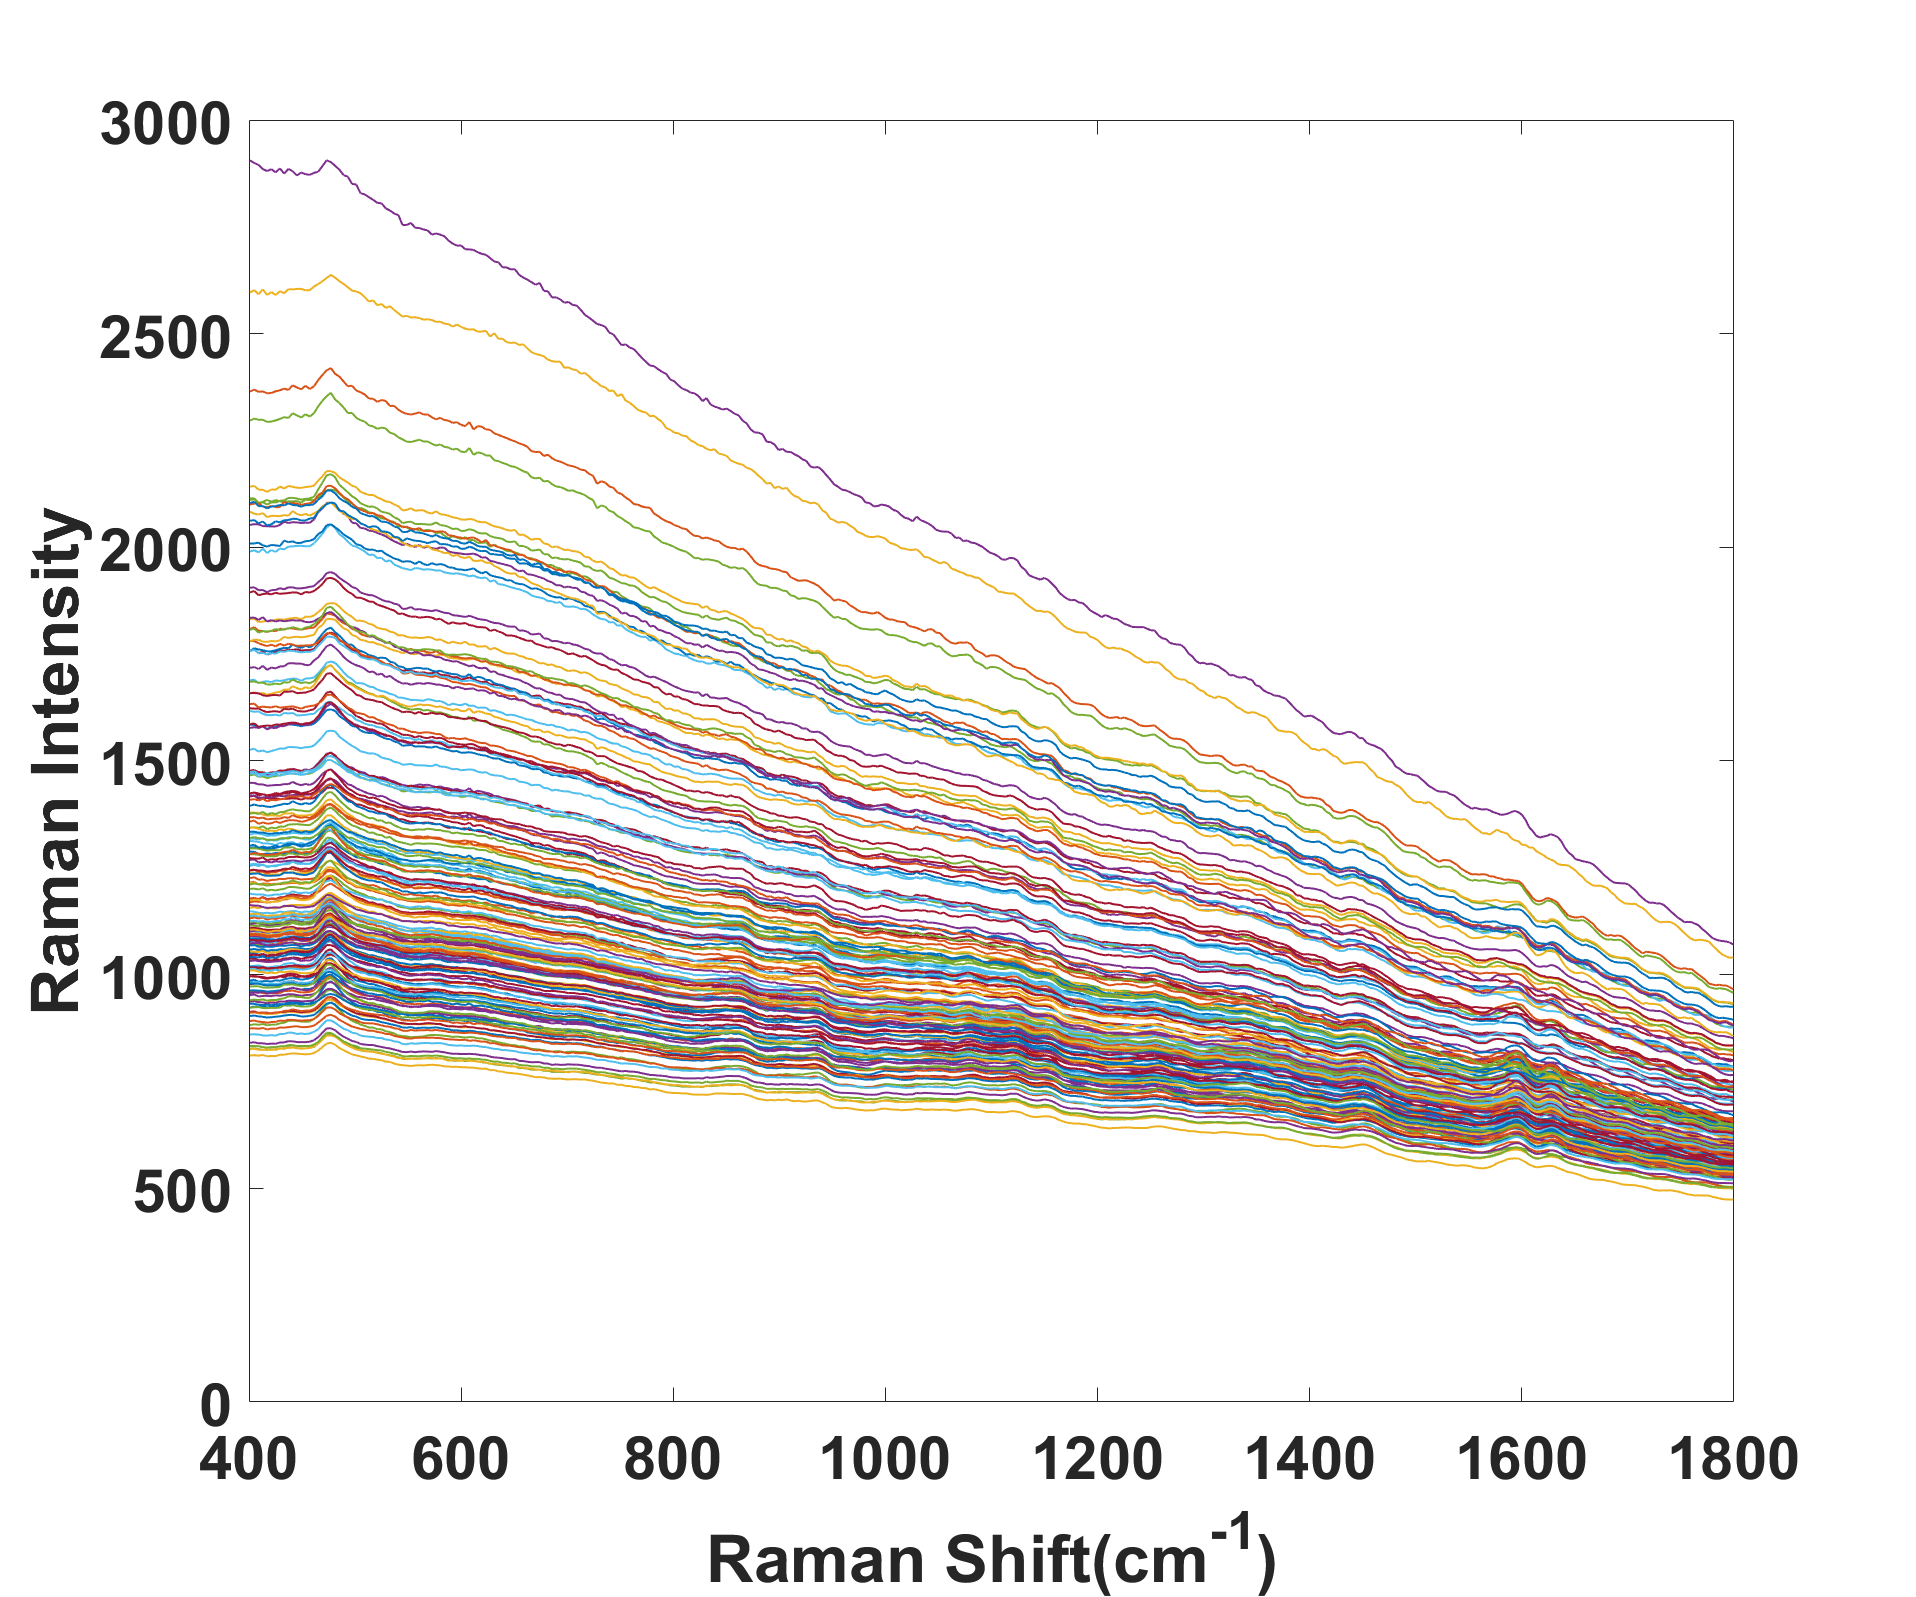

figure('Units','normalized','Position',[0, 0, 0.75, 1]);
for k = 1:size(X_valid_original_noout, 1)
    plot(effshift, X_valid_original_noout(k, :), "LineWidth", 1);
    hold on;
end 
xlim([400, 1800])
xlabel('Raman Shift(cm^{-1})')
ylabel('Raman Intensity')
set(gca,'fontsize',30, 'FontWeight','bold');

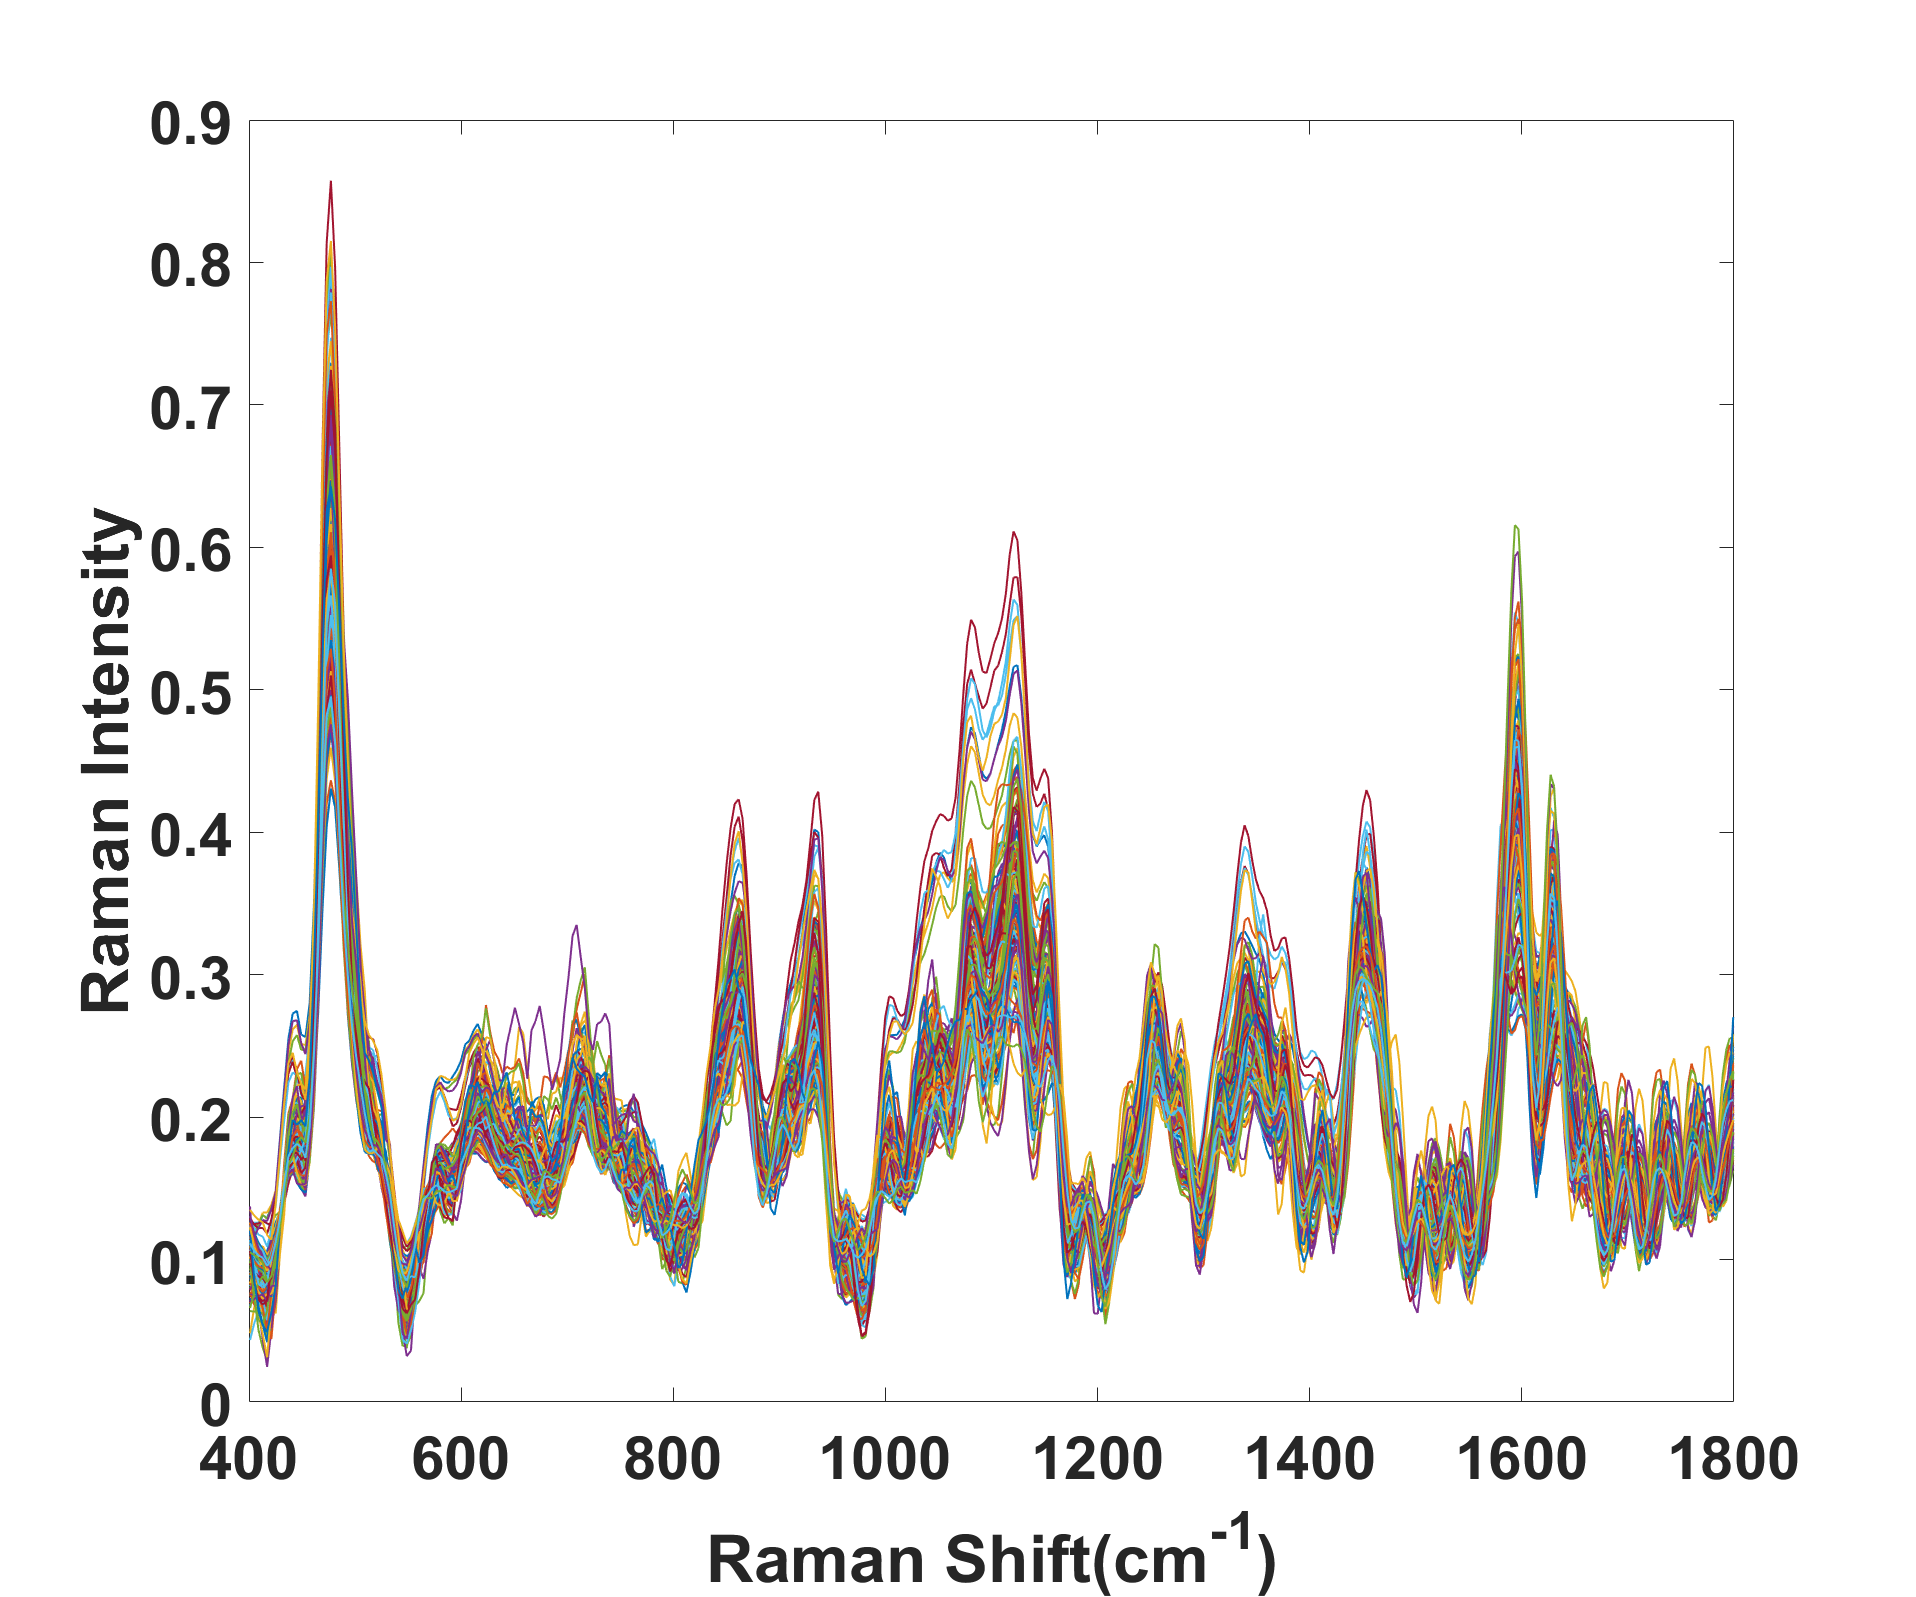

figure('Units','normalized','Position',[0, 0, 0.75, 1]);

for k = 1 : size(X_valid_noout, 1)
    plot(effshift, X_valid_noout(k, :), "LineWidth", 1);
    hold on;
end 

xlim([400, 1800])
xlabel('Raman Shift(cm^{-1})')
ylabel('Raman Intensity')
set(gca,'fontsize',30, 'FontWeight','bold');